**ENGR 20 - MATLAB Programming**

**Homework 4**

**Joseph Park**

**    1. Forward Derivative**

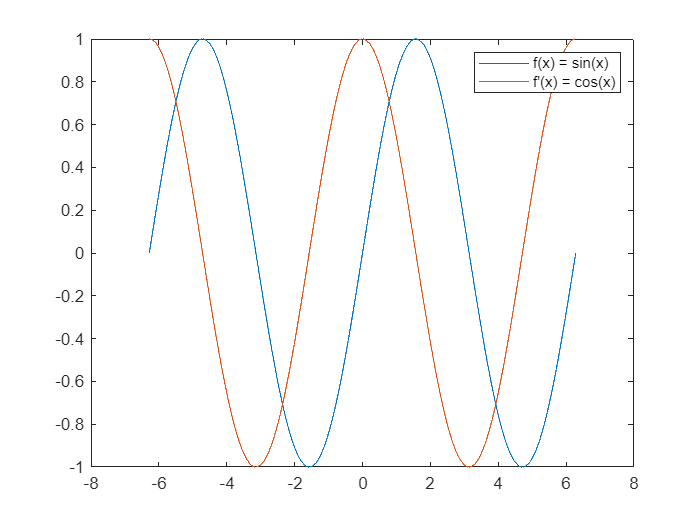

clf;

% Forward Derivative Function
function [output] = forwardDerivative(func, x)
    h = 0.001;
    output = (func(x + h) - func(x)) / h;
end

% Variables
x_values = -2 * pi : 0.001 : 2 * pi;
sin = @(x) sin(x);

% Function plot
plot(x_values, sin(x_values), "DisplayName", "f(x) = sin(x)");

% Forward derivative plot
hold on;
plot(x_values, forwardDerivative(sin, x_values), "DisplayName", "f'(x) = cos(x)");

% Legend
legend();
hold off;

    **2. Projectile Motion with Drag**

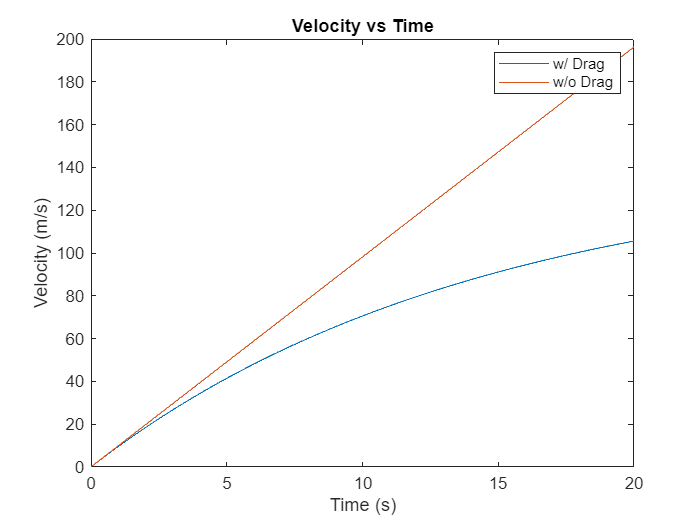

% Used ChatGPT to help understand drag and implement it in MatLab. Tried to
% use recursion initially but kept running into stack overflow errors.
function [velocity] = getVelocity(t)
    m = 10;
    k = 0.7;
    g = 9.81;
    dT = 0.001;
    v0 = 0;
    velocity = v0;
    
    for currentTime = 0:dT:t
        velocity = velocity + dT * (g - (k / m) * velocity);
    end
end

t_vals = 0 : 0.01 : 20;
velocities = zeros(size(t_vals));

for i = 1:length(t_vals)
    velocities(i) = getVelocity(t_vals(i));
end

plot(t_vals, velocities, "DisplayName", "w/ Drag");
hold on;
plot(t_vals, 9.81 * t_vals, "DisplayName", "w/o Drag");
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs Time');
legend();
hold off;

    **3. Monte Carlo Integration**

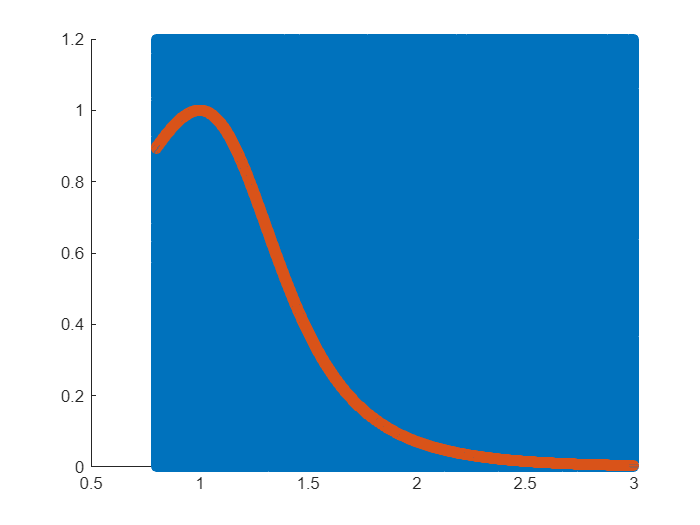

N = 1000000;
x = 0.8 + 2.2 * rand([1,N]);
y = 1.2*rand([1,N]);
scatter(x, y);
hold on;

% The formulas for X and Y are generating random values between 0 and 1,
% multiplying it by the width of that particular side, so that the maximum
% value you can get is that width if the randomly generated value is 1.
% This is being done to a 1-D array 1 x N long, so the variables x and y
% contain a 1-D array with bunch of random values between the intervals.

% Plot the function
x_vals = 0.8 : 0.0001 : 3;
f = @(input) 1 ./ (1 + sinh(2 * input) .* log(input).^2);

scatter(x_vals, f(x_vals));
hold off;

% Out of the 1,000,000 points, how many fall on or below the function
% curve?
g = @(x,y) y - f(x);
N_in = sum(g(x,y) <= 0);
proportion = N_in / N;
area = (2.2) * (1.2) * proportion;
actual = integral(f, 0.8, 3);
per_err = abs(area - actual) / actual * 100;

% Results
disp("Percent Error: " + round(per_err, 3) + "%");

Percent Error: 0.08%
